## **Lab 3: DT Filters -  Non-recursive and Recursive**

## **Problem 1: Non-recursive filters for image deblurring**

In this exercise you will learn how to express DT convolution in a matrix/vector format and how to use this format for deblurring images.

The blurring is implemented using a simple non-recursive DT filter and you will compute the frequency response of the blur filter.

To do this you will need to use the `freqz` command (Tutorial 3.2 in *Computer Explorations*).

**In the following set of tasks, enter and execute your code in the "Code"   sections, and answer the  underlined questions in in a "Text " section following your code section.**

## **Background: Digital Image Representation**

Digital images are made up of many "dots," or pixels (picture elements). By placing these pixels close enough to each other, the images viewed on a computer display or hardcopy appear to be continuous. On a digital computer, the brightness and color information for each pixel is encoded by a number in an array, or, equivalently, an element in a matrix. The location of each value within the array is indexed by two integers, e.g., *X(*3, 4) identifies the pixel value located in the matrix *X* in the third row, fourth column.

Usually the values in the arrays are integers from 0 to $2^n-1$, where *n* is the number of bits used to represent the brightness of each pixel. For example, consider a black-and-white picture where the luminance, or brightness, of each pixel is stored using 8 bits. In this case, the relative brightness of each pixel can be represented as one of 256 possible levels, called gray levels. Usually black is encoded by a value of 0 and white by a value of 255.

The color information for pixels in the image also is usually encoded as integers stored in matrix arrays. In MATLAB, images are stored as integers in arrays and the color information---how each pixel value maps to a certain color--- is stored separately. In this lab exercise, we use a grayscale image.

## **Background: Modeling Linear Blurs for Image Deblurring**

A horizontal motion blur represents a linear system. Horizontal blurring causes each pixel in an image to contain some information from *N* previous pixels of the same row. A simple model of horizontal blurring using DT convolution is

                                       $y[l,n]=\sum_{k=\max(o,n-N+1)}^n x[l,k]h[n-k]$       (1)

where $h[n]$ is  the unit impulse response

                                       
$$h[n]=1/N \; {\rm for} \; n=0, \ldots, N-1$$


and $x[m,n]$ and $y[m,n]$ are arrays of numerical  values that represent values in the original and blurred pictures, respectively. Note that this "blurring" operation corresponds to replacing a pixel values by an average of the surrounding pixel values. The first index denotes the $m$th row, the second index indicates the $n$th column, and the image is $K\times L$. For each row $l$, the DT convolution above in Eq. (1) can be expressed in matrix form as $y_l = H x_l$. 

Specifically, Eq. (1) can be written in matrix form as 

              $\left[
\begin{array}{c}
y[l,0]\\
y[l,1]\\
\vdots\\
y[l,L-1]
\end{array}
\right] 
$=$\left[
\begin{array}{ccccccccc}
h[0] & 0 & 0 & \cdots &  \cdots & \cdots & \cdots & \cdots  &0\\
h[1] & h[0] & 0 & \cdots & \cdots & \cdots & \cdots & \cdots & 0\\
\vdots & \vdots & \vdots & \vdots  & \vdots & \vdots & \vdots & \vdots & \vdots\\
h[N-1] & h[N-2] & h[N-3] & \ldots   & h[0] & 0 &  \ldots & \ldots & 0\\
0 & h[N-1]  & h[N-2]  & \cdots  & \cdots &  h[0] & \cdots & \cdots & 0\\
\vdots & \vdots & \vdots & \vdots  & \vdots & \vdots & \vdots & \vdots & \vdots \\
0 & 0 & 0 & \cdots  & h[N-1] & \cdots & \cdots & h[1] & h[0]\\
\end{array}
\right]$ $\left[
\begin{array}{c}
x[l,0]\\
x[l,1]\\
\vdots\\
x[l,L-1]
\end{array}
\right]$.

The $L \times L$ matrix $H$ has a **banded** structure and is called a Toeplitz matrix. You can use the `toeplitz` command in MATLAB to quickly construct $H$.

If you transpose both sides of the matrix equation above for each row and then form image matrices from the $x$'s and $y$'s, the blurring operation can be represented by

                                  
$$\left[
\begin{array}{ccc}
y[0,0] & \cdots & y[0,L-1] \\
\vdots & \vdots & \vdots \\
y[K-1,0] & \cdots & y[K-1,L-1]
\end{array}
\right]
=
\left[
\begin{array}{ccc}
x[0,0] & \cdots & x[0,L-1] \\
\vdots & \vdots & \vdots \\
x[K-1,0] & \cdots & x[K-1,L-1]
\end{array}
\right]
\cdot
H^{\top}$$


yielding $Y=XH^{\top}$. Since $H$ is square, deblurring can be accomplished by simply inverting the matrix $H^{\top}$  to solve for $X=Y(H^\top)^{-1}$. Note that the matrix ordering is important in the matrix multiplication.

**Task 1. **Load the MATLAB file` Lab3_F23.mat`.  This will load two variables, `tumbller_F23 `(note the strange spelling, with two letters `l`)  and  `map`.

The first contains a blurred image of a vehicle  and the second is a colormap.

Then show the blurred image  `tumbller_F23` by entering the MATLAB commands:

`imshow(tumbller_F23)`

`colormap(map)`

load Lab3_F23.mat
imshow(tumbller_F23)

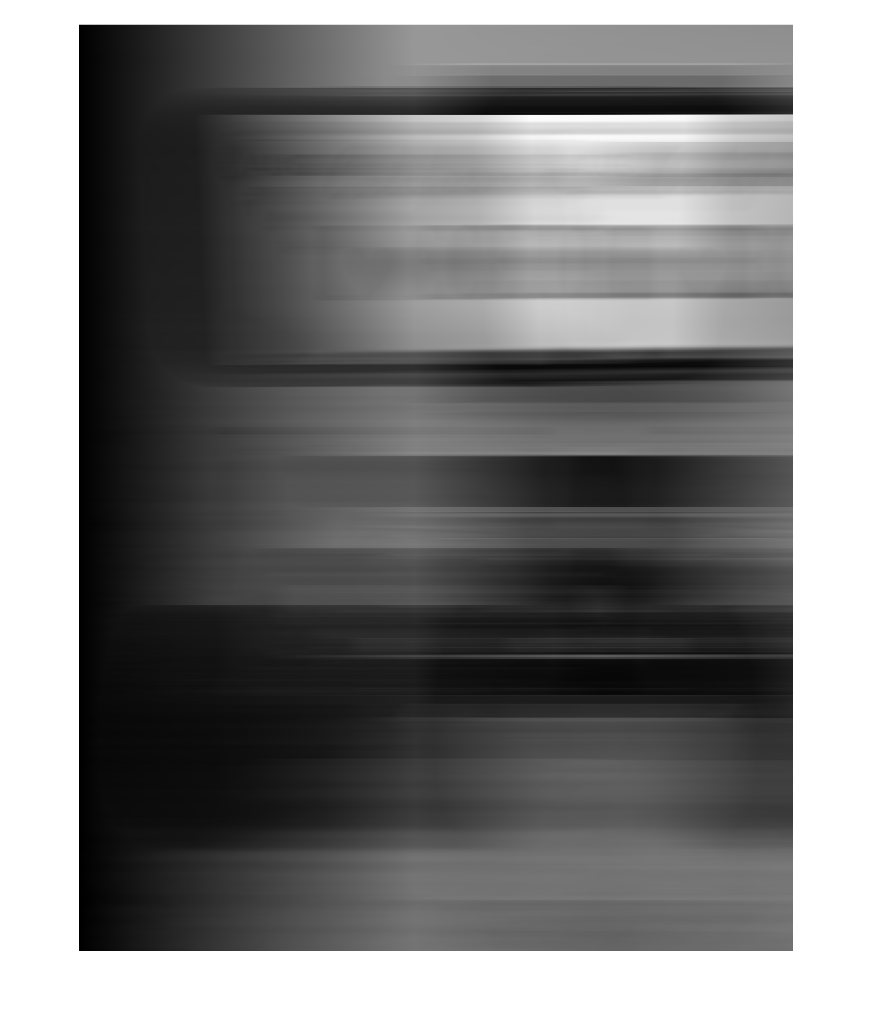

colormap(map)

size(tumbller_F23)

ans =         2562        1975


**Task 2. **Figure out how many of the previous pixel values are affecting each pixel in the same row of the blurred image (i.e., find the length $N$ of the blur filter) by trial and error. 

To do this, write an M-file with a function called `deblur` to deblur the image for different values of $N$.  The value of $N$ will be between 1 and the number of columns in the image. When you can see the vehicle and identify the license plate number of the car (a vanity plate), you have found the correct value of $N$. With exactly the correct value of $N$, you will see the image with no distortion artifacts, such as vertical bands, shifted parts of the image, black-white inversion, or faint ghosts (even on Halloween). If you are off by even just 1, you will see some of these effects.   

Determine the size of the image.   Run your function with the correct value of $N$ and show the resulting deblurred image.

Identify the state, license plate number, the registration date (month and year), and the exact length $N$ of the blur.

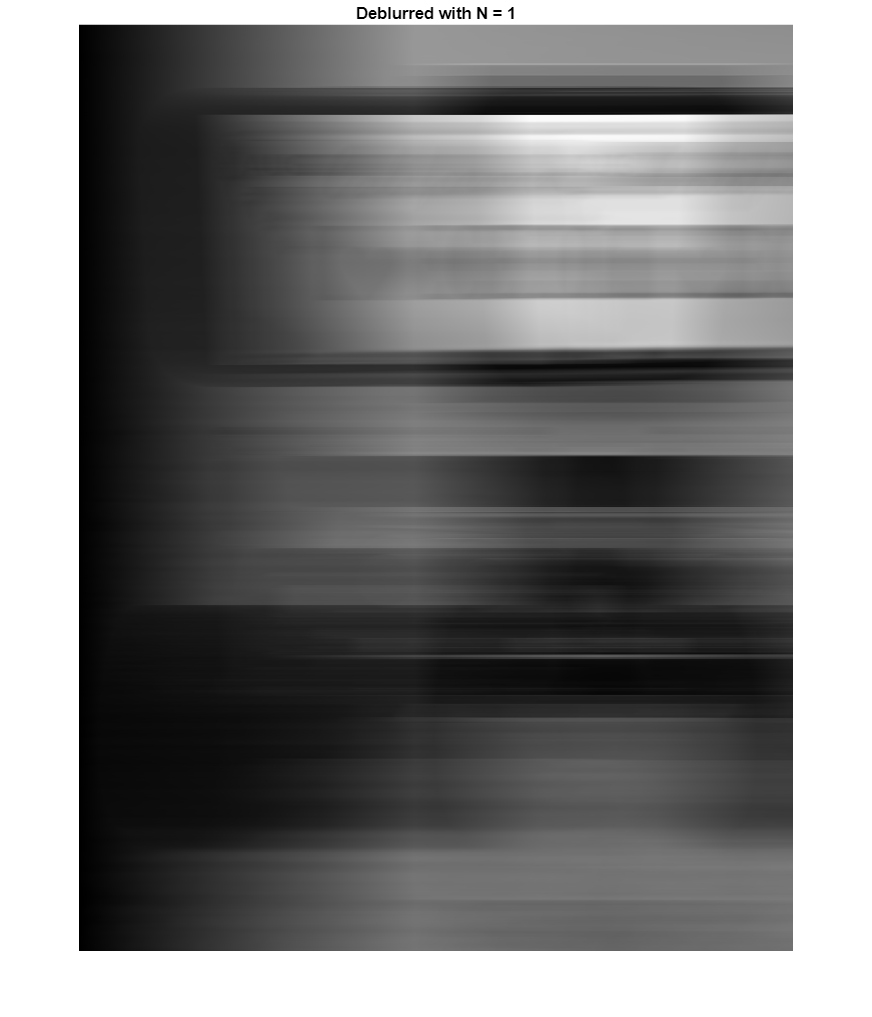

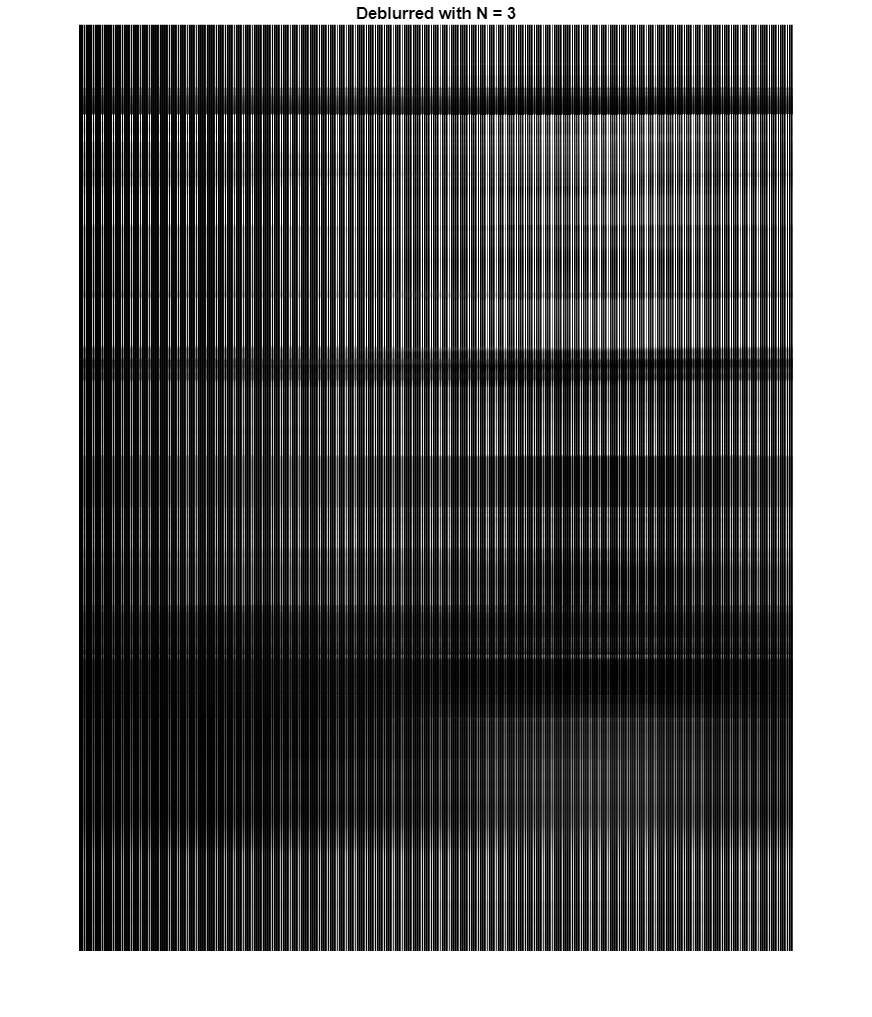

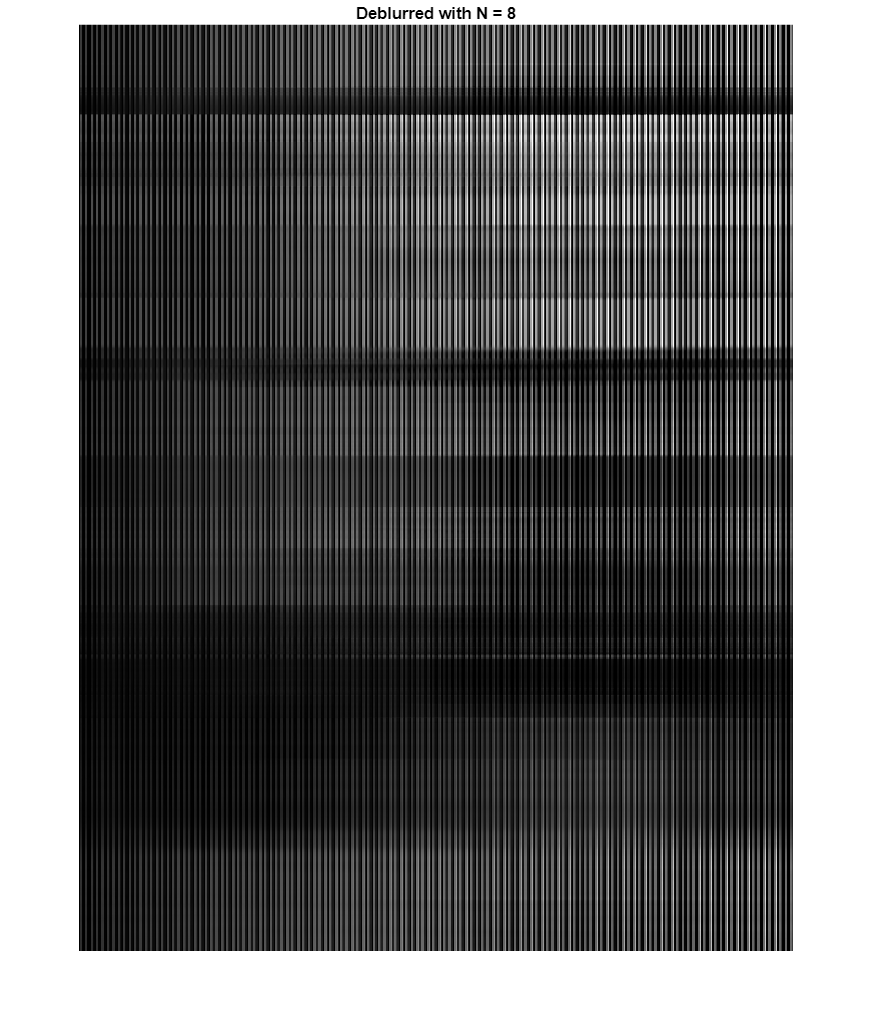

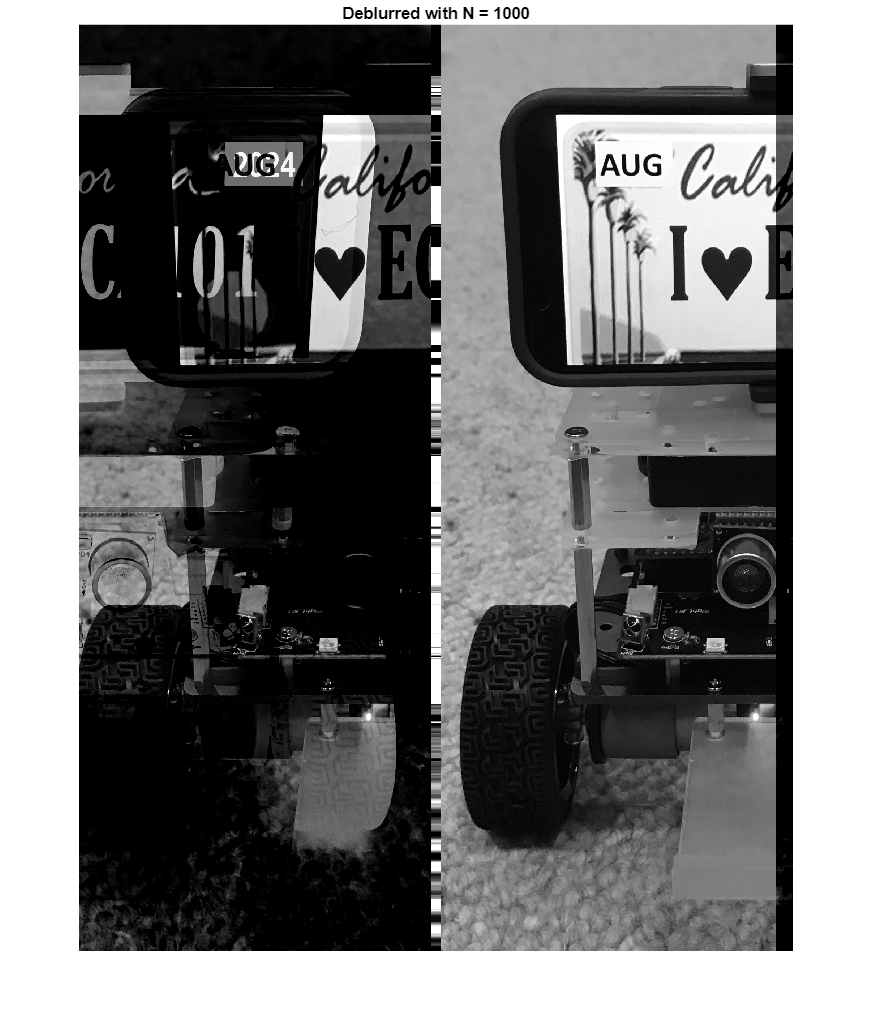

 % Load blurred image
for N_test = [1, 3, 8, 1000]  % Try different N values
    X_restored = deblur(tumbller_F23, N_test);
    figure, imshow(X_restored), title(['Deblurred with N = ', num2str(N_test)]);
end

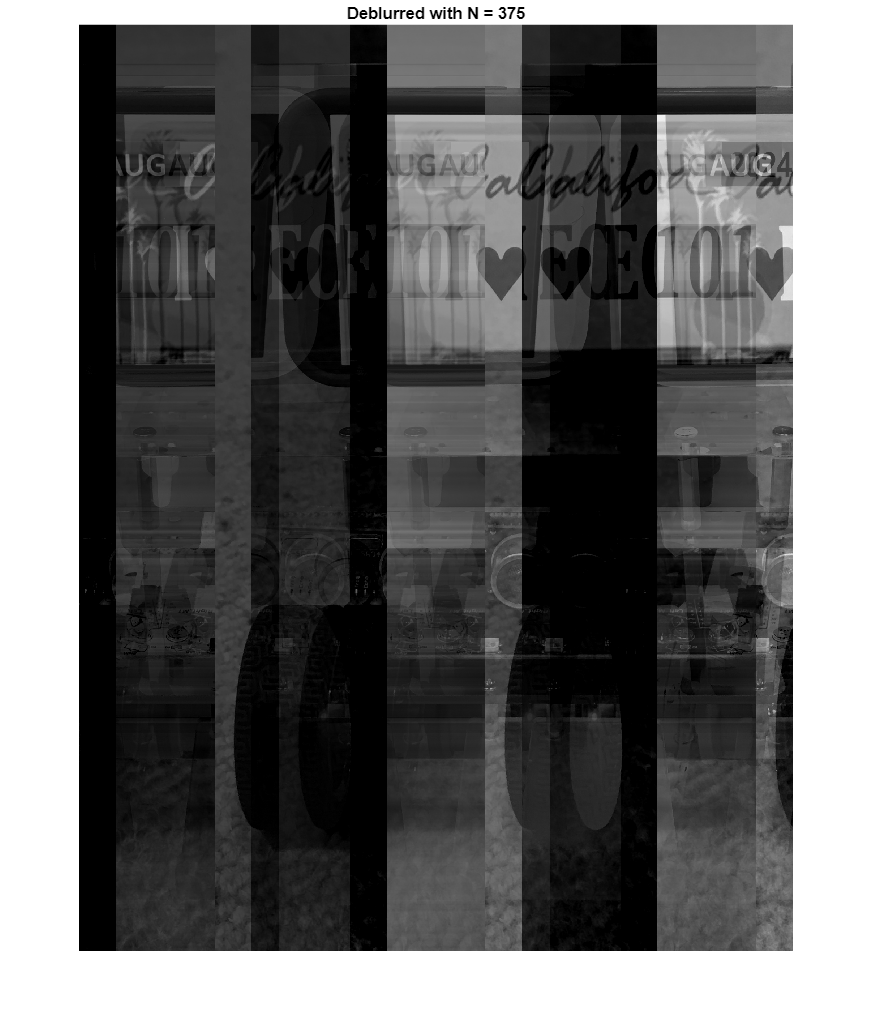

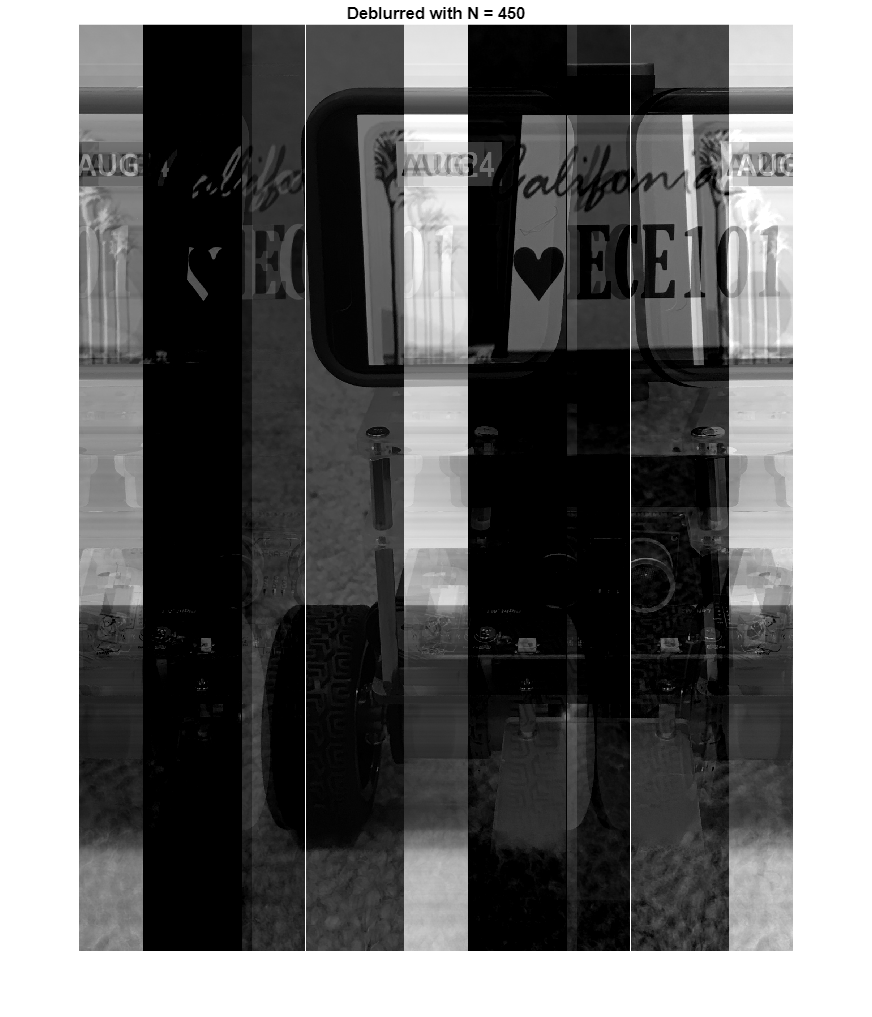

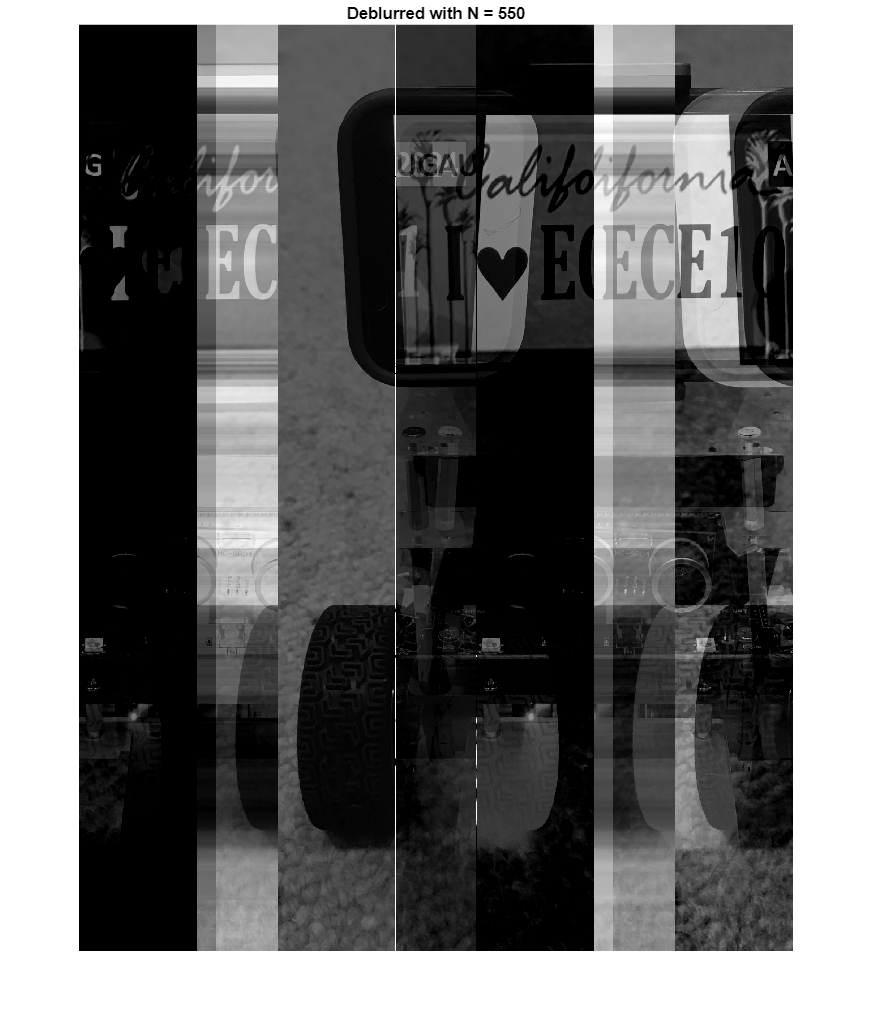

for N_test = [375, 450, 550]  % Try different N values
    X_restored = deblur(tumbller_F23, N_test);
    figure, imshow(X_restored), title(['Deblurred with N = ', num2str(N_test)]);
end

We can clearly see that the liscence plate says I (heart) ECE101, and also that trial and error is a bad way to find something, however linear search also sucks when the runtime of a "search" crashes your computer after enough trials

**Task 3:** Print out the deblurring results for at least 4 incorrect values of $N$that you tried. (If you got the correct $N$ in fewer tries, try a variety of at least 4 incorrect values anyway.) 

Based upon what you see with a few different incorrect values of $N$, how would you characterize an improperly deblurred image? (Your answer can be qualitative.)

The deblurring results for at least 4 incorrect values are shown above, the imporperly deblurred image looks like column of the image shifted on itself a number of times, with smaller N looking like larger blocky columns, while larger N looks like more iterations that capture the details

**Task 4. **Write a difference equation for the length-$N$ blur filter. Write the impulse  response $h[n]$.

y[n] = Sum_{k=0}^{N-1} x[n-k] h[k]

h[n] = 1/N

y[n] = 1/n * Sum_{k=0}^{N-1} x[n-k]

Ny[n] = x[n] + x[n-1] + ... + x[n- N +1]

**Task 5. **Now, consider blur filters of length N=3 and N=8.  

**Part 1. **Analytically determined the frequency responses $H(e^{j\omega})$of each of these two blur filters.

Plot the magnitudes $|H(e^{j\omega})|$.

When N = 3

The filter averages each pixel with its two preceding values.

The image retains more details since the averaging window is small, but still vertical lines.

When N = 8

The filter averages each pixel with its seven preceding values.

The lines are thinner

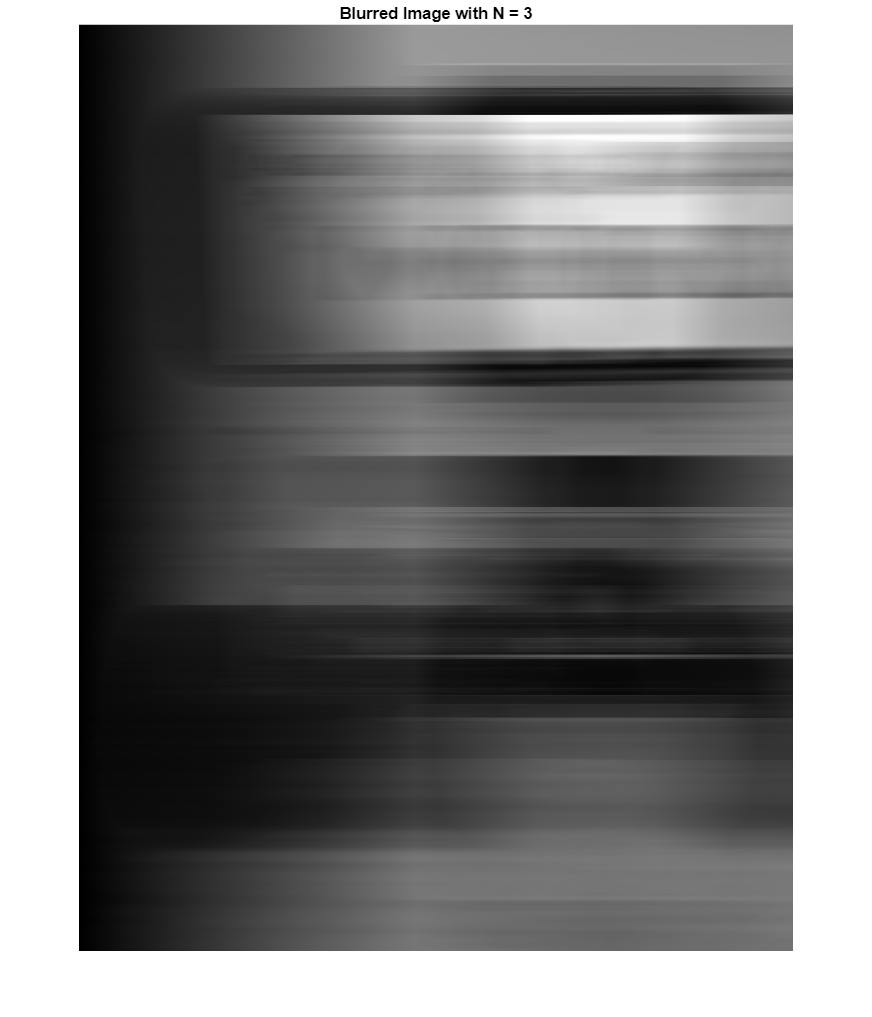


    N = 3;
    figure;
    % Create the blur filter (impulse response)
    h = ones(1, N) / N;  
    
    % Apply convolution to blur the image
    blurred_image = conv2(tumbller_F23, h, 'same');
    
    imshow(blurred_image, []);
    colormap(map);
    title(['Blurred Image with N = ', num2str(N)]);

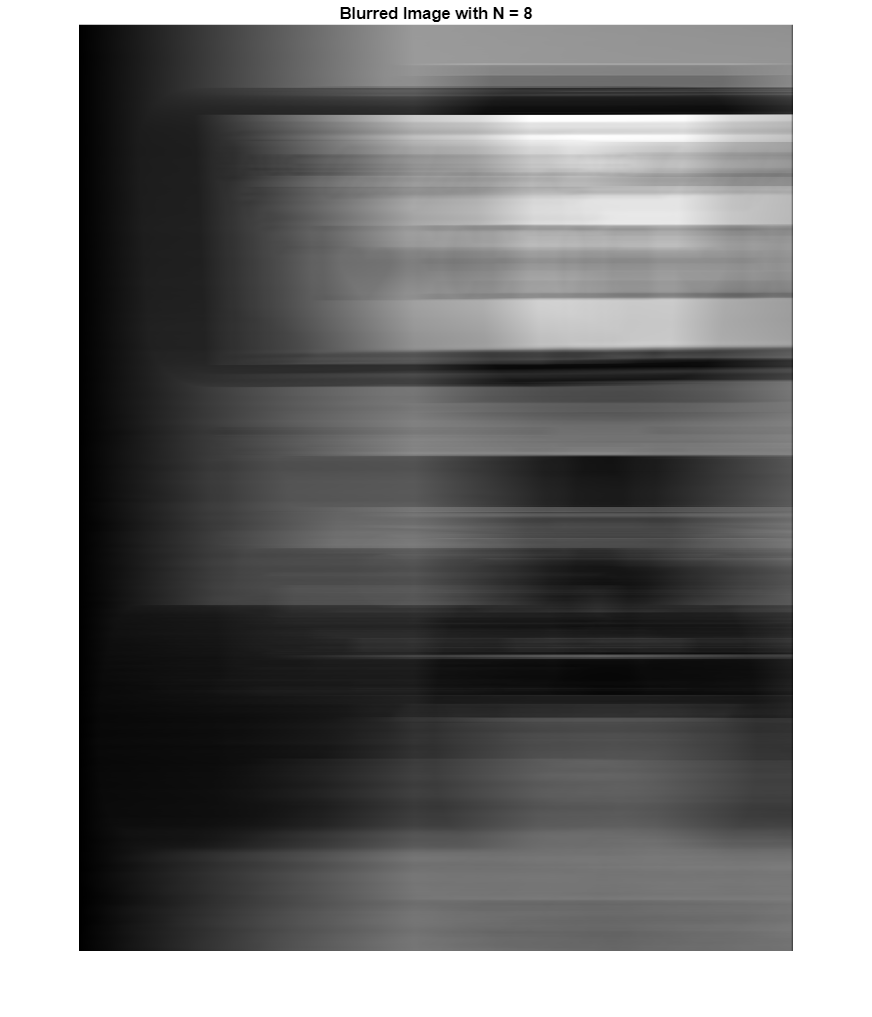

    N = 8;
    figure;
    % Create the blur filter (impulse response)
    h = ones(1, N) / N;  
    
    % Apply convolution to blur the image
    blurred_image = conv2(tumbller_F23, h, 'same');
    
    % Display the blurred images
    
    imshow(blurred_image, []);
    colormap(map);
    title(['Blurred Image with N = ', num2str(N)]);

**Part 2.** Use the `freqz` command to evaluate the frequency response $H(e^{j\omega})$ of each of these filters at 1024 points between 0 and 2π. You should use the '`whole`' option with `freqz` to do this.

Use `plot` and `abs` to generate appropriately labeled graphs of the magnitude of the frequency response for these systems. Include plots where the  magnitude  is shown on a linear  and on a  decibel (dB) scale, with `xdB =20*log10(abs(x)).`

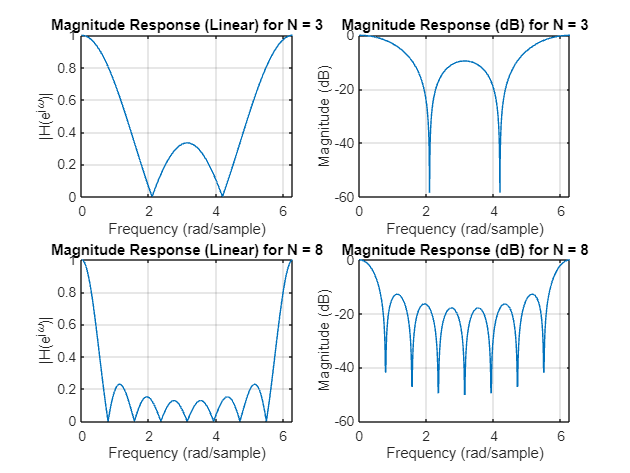

% Define blur filter lengths
N_values = [3, 8];

% Frequency response analysis
figure;
for i = 1:length(N_values)
    N = N_values(i);
    
    % Create the impulse response of the blur filter
    h = ones(1, N) / N;
    
    % Compute frequency response
    [H, w] = freqz(h, 1, 1024, 'whole'); 
    
    % Plot magnitude response (linear scale)
    subplot(2,2,2*i-1);
    plot(w, abs(H));
    title(['Magnitude Response (Linear) for N = ', num2str(N)]);
    xlabel('Frequency (rad/sample)');
    ylabel('|H(e^{j\omega})|');
    grid on;
    
    % Plot magnitude response (dB scale)
    subplot(2,2,2*i);
    plot(w, 20*log10(abs(H)));  
    title(['Magnitude Response (dB) for N = ', num2str(N)]);
    xlabel('Frequency (rad/sample)');
    ylabel('Magnitude (dB)');
    grid on;
end

**Part 3:** Looking at your results of Parts 1 and 2, would you say that blur filters have low-pass or high-pass filter characteristics? How does the filter behavior depend on the filter length$N$?  

Looking at the graphs it looks like it has both, representing more of a band stop filter, or a notch filter. The notch becomes more ideal with a higher N. 

## **Problem 2: First-order recursive DT filters**

This exercise is taken from Section 3.8, "First-Order Recursive Discrete-Time Filters" in *Computer Explorations in SIGNALS AND SYSTEMS [2nd edition]* by Buck, Daniel, Singer.  In this exercise, you will explore the effect of first-order* recursive* discrete-time filters on discrete-time periodic signals. You will need to use the `fft` and` ifft` commands (Tutorial 3.1), as well as the  `filter` command (Tutorial 2.2).

The exercise focuses on two causal LTI systems described by first-order recursive difference equations:

                            System 1:  $y[n]-0.8 y[n-1] = x[n]$

                            System 2:  $y[n]+0.8 y[n-1] = x[n]$

The input signal $x[n]$ you will apply to both systems will be the periodic signal with period $N=20$ described by the DTFS coefficients

                               $a_k = \left\{ \begin{array}{rl}
-4/5, & k=\pm1,\\
2/5, & k=\pm 9,\\
0, & \rm{otherwise.}\\
\end{array}
\right.$         (1)

**Task 1.**   Analytically determined the frequency response $H(e^{j\omega})$of each of these systems.   

Plot the magnitudes $|H(e^{j\omega})|$.

get H = 1/ 1-.8e^-jw

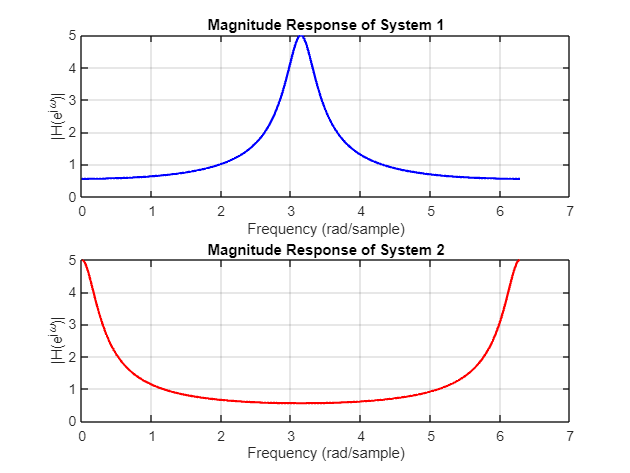

% Define frequency range
w = linspace(0, 2*pi, 1024); 

% Compute frequency responses
H2=  1 ./ (1 - 0.8 * exp(-1j*w));  
H1 = 1 ./ (1 + 0.8 * exp(-1j*w));  

% Plot magnitude responses
figure;
subplot(2,1,1);
plot(w, abs(H1), 'b', 'LineWidth', 1.5);
title('Magnitude Response of System 1');
xlabel('Frequency (rad/sample)');
ylabel('|H(e^{j\omega})|');
grid on;

subplot(2,1,2);
plot(w, abs(H2), 'r', 'LineWidth', 1.5);
title('Magnitude Response of System 2');
xlabel('Frequency (rad/sample)');
ylabel('|H(e^{j\omega})|');
grid on;

**Task 2. **Define vectors `a1` and `b1` for the difference equation describing System 1 in the format specified by` filter` and `freqz`. Similarly, define `a2` and `b2` to describe System 2.

% System 1 coefficients
b1 = [1];  
a1 = [1, -0.8];

% System 2 coefficients
b2 = [1];  
a2 = [1, 0.8];


**Task 3. **Use `freqz` to evaluat the frequency response of Systems 1 and 2 at 1024 points between 0 and $2\pi$. Note that you will again have to use the '`whole`' option with freqz to do this.  Use `plot` and `abs` to generate appropriately labeled graphs of the magnitude of the frequency response for these systems (dB scale only). Based  on the frequency response plots, specify whether each system  in a highpass, lowpass, or bandpass filter. 

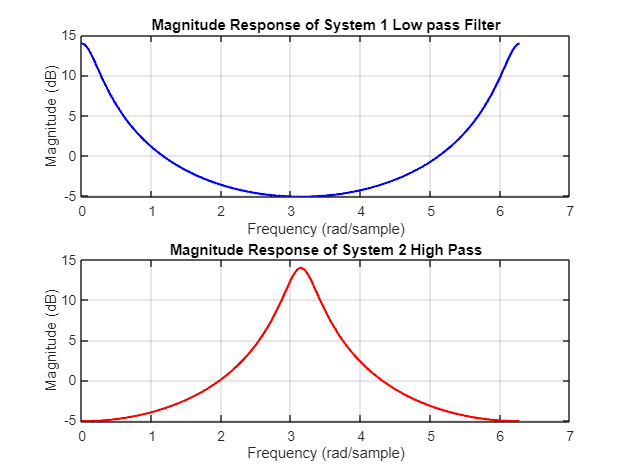

% Define frequency range
N = 1024;  % Number of points
[H1, w] = freqz(b1, a1, N, 'whole');  % System 1
[H2, ~] = freqz(b2, a2, N, 'whole');  % System 2

% Convert to dB scale
H1_dB = 20 * log10(abs(H1));
H2_dB = 20 * log10(abs(H2));

% Plot magnitude response in dB
figure;
subplot(2,1,1);
plot(w, H1_dB, 'b', 'LineWidth', 1.5);
title('Magnitude Response of System 1 Low pass Filter');
xlabel('Frequency (rad/sample)');
ylabel('Magnitude (dB)');
grid on;

subplot(2,1,2);
plot(w, H2_dB, 'r', 'LineWidth', 1.5);
title('Magnitude Response of System 2 High Pass');
xlabel('Frequency (rad/sample)');
ylabel('Magnitude (dB)');
grid on;

%type designated in plot titles (the w is plotted different so it looks
%like a notch and bandpass

**Task 4. **Use Eq. (1) to define the vector `a_x to be the DTFS  coefficients of `$x[n]$ for $0\leq k \leq19$.  Generate a plot of the DTFS coefficients using` stem where the `$x$-axis is labeled with frequency $\omega_k=(2\pi/20)k$. Compare the plot with the frequency responses you generated  in Task 1 and Task 3, and for each system state which frequency components willl be amplified  and which will be attenuated  when $x[n]$ is the input to the system.

ak is -4/6 when |k| = 1, 2/5 |k| = 9 and 0 otherwise

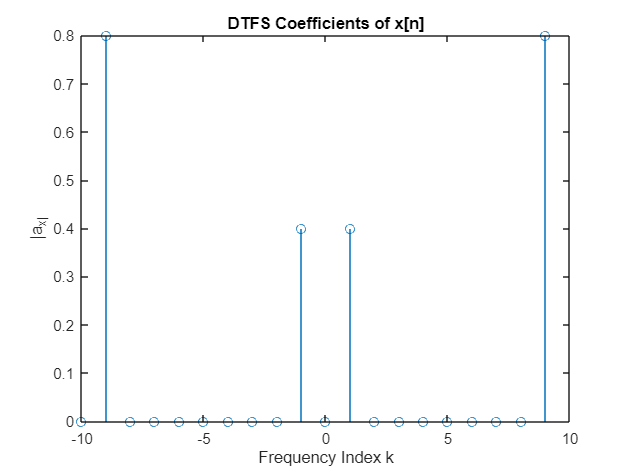

N = 20;
a_x = zeros(1, N);
a_x([2, end]) = -4/5; % k = ±1
a_x([10, end-8]) = 2/5; % k = ±9

k = -floor(N/2):floor(N/2)-1;
figure;
stem(k, abs(a_x));
xlabel('Frequency Index k'); ylabel('|a_x|');
title('DTFS Coefficients of x[n]');

system 1 will pass through the lower frequencies while system 2 will amplify higher freqs

**Task 5.  **Use the results of Task 1 to analytically determine the coefficients $b_{1,k}$ and $b_{2,k}$ of the output signals produced by System 1 and System 2.

Use` stem` and` abs` to generate plots of the magnitudes of the DTFS coefficients for both sequences. Do your results agree with your conclusions in Task 4?

each new coeff is just the product of the transfer function * the original coeff

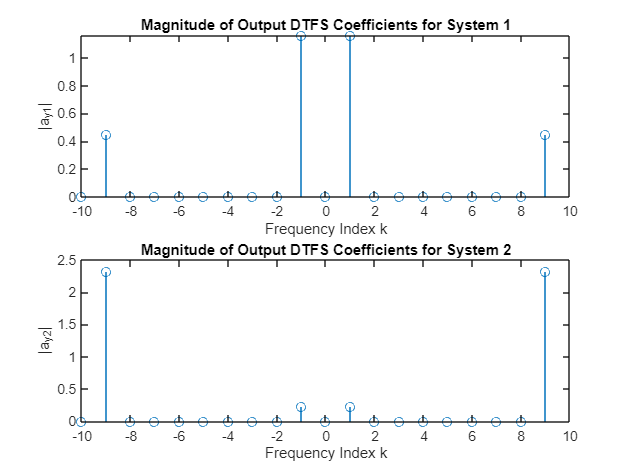

H1_k = 1 ./ (1 - 0.8*exp(-1j*2*pi*k/N));
H2_k = 1 ./ (1 + 0.8*exp(-1j*2*pi*k/N));

a_y1 = H1_k .* a_x;
a_y2 = H2_k .* a_x;

figure;
subplot(2,1,1);
stem(k, abs(a_y1));
title('Magnitude of Output DTFS Coefficients for System 1');
xlabel('Frequency Index k'); ylabel('|a_{y1}|');

subplot(2,1,2);
stem(k, abs(a_y2));
title('Magnitude of Output DTFS Coefficients for System 2');
xlabel('Frequency Index k'); ylabel('|a_{y2}|');

These graphs show better how the first system filters out higher frequencies while the second amplifies larger signals and dampens or filters lower frequency signals, (low pass, high pass)

**Task 6. **Define` x_20` to be one period of  $x[n]$ for $0\leq n \leq 19$ using `ifft` with `a_x `as specified in Tutorial 3.1.  Use `x_20` to create `x`, consisting of 6 periods of $x[n]$ for $-20\leq n\leq 99$. Also define `n` to be this range of sample indices, and generate a plot of $x[n]$ on this interval using `stem`. 

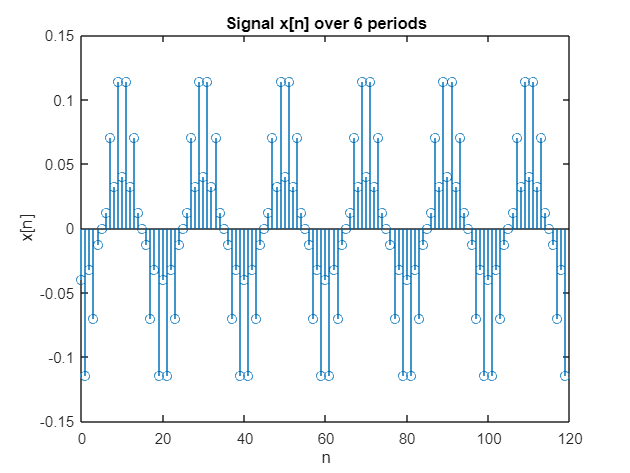

x_20 = ifft(a_x, 'symmetric');
x = repmat(x_20, 1, 6);
n = 0:length(x)-1;

figure;
stem(n, x);
title('Signal x[n] over 6 periods');
xlabel('n'); ylabel('x[n]');

**Task 7. **Use `filter` to compute `y1` and `y2`, the outputs of Systems 1 and 2 when $x[n]$ is the input. Plot both outputs for $0 \leq n \leq 99$ using `stem`.  Based on these plots, state which output contains more high frequency energy and which has more low frequency energy. Do the plots confirm your answers in Task 4 and Task 5?

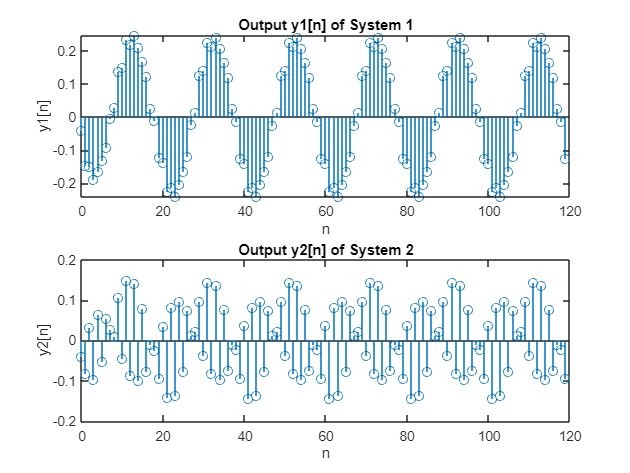

 y1 = filter(b1, a1, x);
y2 = filter(b2, a2, x);

figure;
subplot(2,1,1);
stem(n, y1);
title('Output y1[n] of System 1');
xlabel('n'); ylabel('y1[n]');

subplot(2,1,2);
stem(n, y2);
title('Output y2[n] of System 2');
xlabel('n'); ylabel('y2[n]');

Based on these plots, the output contains more low frequency energy for y2 and high for y1 which confirms what we found from the plots in the previous tasks

**Task 8. **Define `y1_20` and `y2_20` to be the segments of `y1` and `y2` corresponding to $y_1[n]$ and $y_2[n]$ for $0 \leq n \leq 19$.Use these  vectors and `fft`  to   compute `a_y1` and `a_y2`, the DTFS coefficients of `y1` and `y2`. Use` stem` and` abs` to generate plots of the magnitudes of the DTFS coefficeints for both sequences. 

Are these plots consistent with your answers in Task 7? 

Do they differ from your analytical results in Part 5? If so, try to explain why.

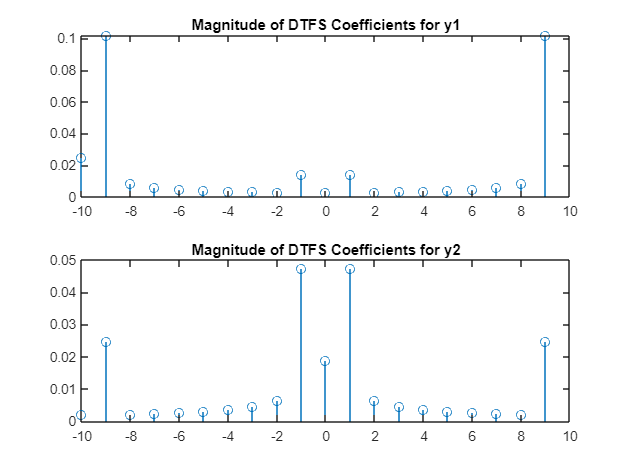

y1_20 = y1(1:N);
y2_20 = y2(1:N);

a_y1 = fft(y1_20) / N;
a_y2 = fft(y2_20) / N;

figure;
subplot(2,1,1);
stem(k, abs(a_y1));
title('Magnitude of DTFS Coefficients for y1');

subplot(2,1,2);
stem(k, abs(a_y2));
title('Magnitude of DTFS Coefficients for y2');

The plots show y2 has most of its energy in the low frequency while y1 has it in the higher freqency

the results would only differ in small amounts due to limitations from fft but for the most part the observations should be the same because the system transfer function describes how the system works

## **Functions**

function N = deblur(Y,X)

L = size(Y, 2); %cols
h = ones(1, X) / X;
H = toeplitz([h, zeros(1, L-X)]);
N = Y * pinv(H');
end